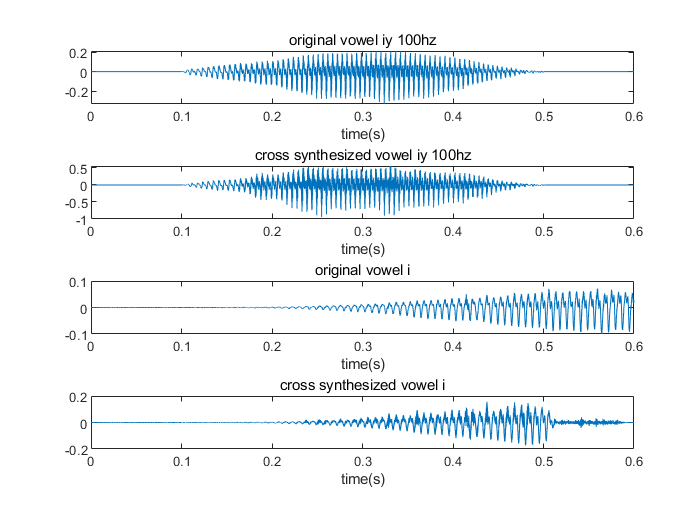

[s1,fs1]=audioread('vowel_iy_100hz.wav');
[s2,fs2]=audioread('i.wav');

framesize=320;
frameshift=80;
order=12;
window=hamming(framesize);

sig_hat_vowel=zeros(1,length(s1));
sig_hat_i=zeros(1,length(s2));

[a0_vowel,error0_vowel]=LPC(s1(1:framesize)'.*window',order);
[a0_i,error0_i]=LPC(s2(1:framesize)'.*window',order);
framepad0_vowel=[zeros(1,order),s1(1:framesize)'];
framepad0_i=[zeros(1,order),s2(1:framesize)'];
for n=1:framesize
    for k=1:order
        sig_hat_vowel(n)=sig_hat_vowel(n)+a0_i(k).*framepad0_vowel(order+n-k);
        sig_hat_i(n)=sig_hat_i(n)+a0_vowel(k).*framepad0_i(order+n-k);
    end
end
sig_hat_vowel(1:framesize)=sig_hat_vowel(1:framesize)+error0_vowel;
sig_hat_i(1:framesize)=sig_hat_i(1:framesize)+error0_i;


for n=2:(length(s1)-framesize)/frameshift

    frame_vowel=s1((n-1)*frameshift+1:(n-1)*frameshift+framesize)'.*window';

    [a1,error1]=LPC(frame_vowel,order);
    
    frame_i=s2((n-1)*frameshift+1:(n-1)*frameshift+framesize)'.*window';

    [a2,error2]=LPC(frame_i,order);
    
    framepad_vowel=[zeros(1,order),frame_vowel];
    framepad_i=[zeros(1,order),frame_i];
    for i=(n-1)*frameshift+1:(n-1)*frameshift+framesize
            for k=1:order
                sig_hat_vowel(i)=sig_hat_vowel(i)+a2(k).*framepad_vowel(order+(i-(n-1)*frameshift)-k);
                %disp(sig_hat_vowel(i))
                sig_hat_i(i)=sig_hat_i(i)+a1(k).*framepad_i(order+(i-(n-1)*frameshift)-k);
                
            end
    end
    sig_hat_vowel((n-1)*frameshift+1:(n-1)*frameshift+framesize)=sig_hat_vowel((n-1)*frameshift+1:(n-1)*frameshift+framesize)+error1;
    sig_hat_i((n-1)*frameshift+1:(n-1)*frameshift+framesize)=sig_hat_i((n-1)*frameshift+1:(n-1)*frameshift+framesize)+error2;  
end

figure
subplot(4,1,1);
plot(1/fs1:1/fs1:length(s1)/fs1,s1);
title('original vowel iy 100hz');
xlabel('time(s)');

subplot(4,1,2);
plot(1/fs1:1/fs1:length(s1)/fs1,sig_hat_vowel);
title('cross synthesized vowel iy 100hz');
xlabel('time(s)');

subplot(4,1,3);
plot(1/fs1:1/fs1:length(s1)/fs1,s2(1:length(s1)));
title('original vowel i');
xlabel('time(s)');

subplot(4,1,4);
plot(1/fs1:1/fs1:length(s1)/fs1,sig_hat_i(1:length(s1)));
title('cross synthesized vowel i');
xlabel('time(s)');


audiowrite('cross synthesized vowel_iy_100hz.wav',sig_hat_vowel,fs1);
audiowrite('cross synthesized i.wav',sig_hat_i,fs2);
